%% SETUP: Parameters
% We descend p from 1.9 to 1.1 as per paper recommendation
p_values = [1.8, 1.6, 1.4, 1.2]; 

% Start with the Phase 1 result (Standard Spectral, p=2)
current_f = v2; 

% Optimization Parameters (Manual Gradient Descent)
learning_rate = 0.02; % How big of a step to take
max_steps = 2000;       % Steps per p-value (fast updates)

fprintf('Starting Manual p-Spectral Optimization (Derivative-Based)...\n');

Starting Manual p-Spectral Optimization (Derivative-Based)...



%% MAIN LOOP (Algorithm 1 Implementation)
for p = p_values
    fprintf('Optimizing for p = %.1f ', p);
    
    % Iterative Update (Gradient Descent)
    % This replaces 'fminunc' by doing the math manually
    for step = 1:max_steps
        % 1. Calculate the Derivative (Gradient)
        % This tells us which direction is "downhill"
        grad = get_p_gradient(current_f, W, p);
        
        % 2. Move in that direction
        current_f = current_f - learning_rate * grad;
        
        % 3. Re-normalize to prevent it from shrinking to zero
        % (The paper minimizes over a norm constraint)
        current_f = current_f / norm(current_f);
    end
    
    % Calculate final value for this p to show progress
    val = calculate_Fp(current_f, W, p);
    fprintf('-> Final F_p: %.5f\n', val);
end

Optimizing for p = 1.8 

-> Final F_p: 0.00337


Optimizing for p = 1.6 

-> Final F_p: 0.01032


Optimizing for p = 1.4 

-> Final F_p: 0.22243


Optimizing for p = 1.2 

-> Final F_p: 0.86878



final_f = current_f;
disp('Optimization Complete.');

Optimization Complete.


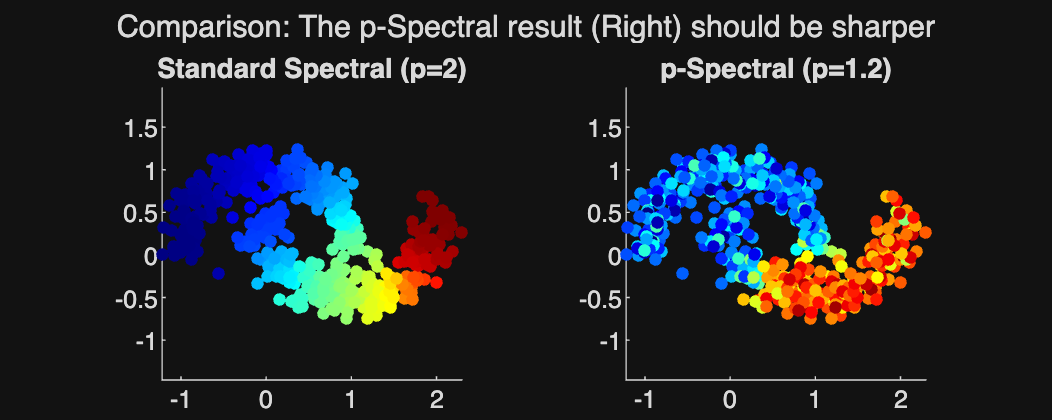


%% PLOTTING RESULTS
figure('Position', [100, 100, 1000, 400]);

% 1. Standard Result (p=2)
subplot(1, 2, 1);
scatter(X(:,1), X(:,2), 20, v2, 'filled');
title('Standard Spectral (p=2)');
colormap(jet); axis equal;

% 2. p-Laplacian Result (p=1.2)
subplot(1, 2, 2);
scatter(X(:,1), X(:,2), 20, final_f, 'filled');
title(sprintf('p-Spectral (p=%.1f)', p_values(end)));
colormap(jet); axis equal;

sgtitle('Comparison: The p-Spectral result (Right) should be sharper');



%% FINAL STEP: Thresholding (Eq. 3 in Paper)
% The paper says: "Threshold the eigenvector to obtain the partition"
% We sweep through possible cuts and pick the best Ratio Cheeger Cut (RCC).

fprintf('Performing Optimal Thresholding (Eq. 3)...\n');

Performing Optimal Thresholding (Eq. 3)...


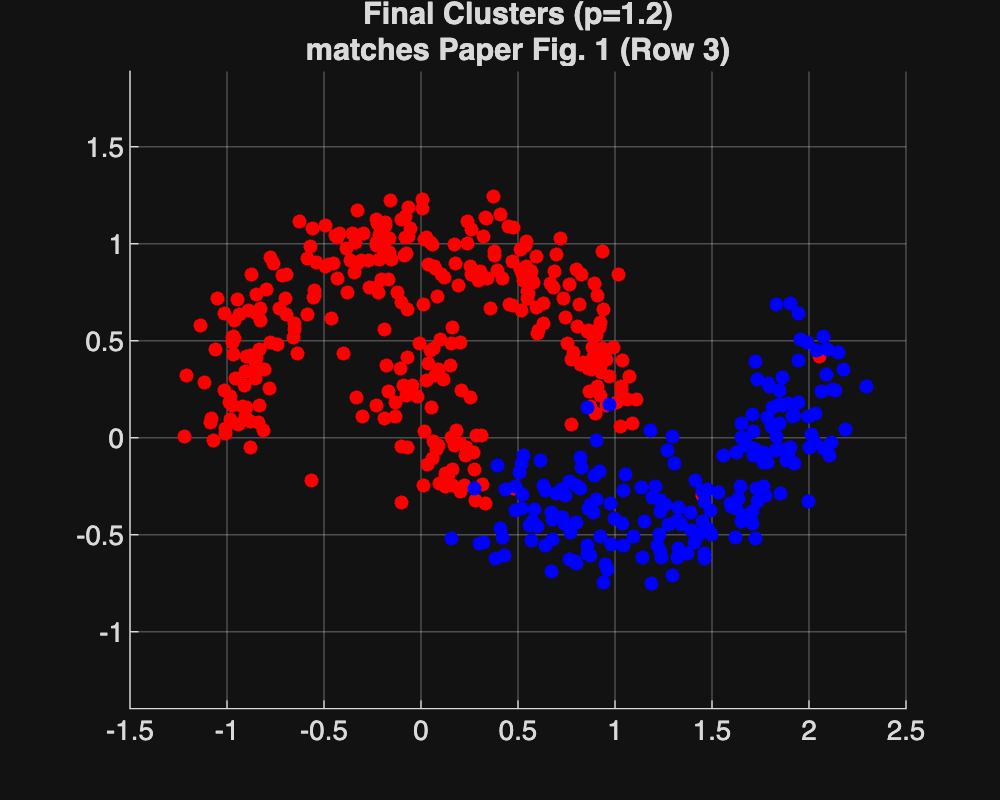


best_rcc = Inf;
best_labels = zeros(n_samples, 1);
sort_f = sort(final_f);

% Test 50 possible thresholds
for i = 1:50
    % Pick a threshold value from the sorted vector
    idx = floor(i * n_samples / 50); 
    if idx == 0, idx=1; end
    t = sort_f(idx);
    
    % Create Clusters based on threshold t
    labels = final_f > t; % 1 if > t, 0 otherwise
    
    % Skip invalid cuts (all 0 or all 1)
    if sum(labels) == 0 || sum(labels) == n_samples
        continue;
    end
    
    % --- Calculate Cheeger Cut (Simplified for Speed) ---
    cluster1 = find(labels);
    cluster2 = find(~labels);
    
    % Count edges between Cluster 1 and Cluster 2
    % (Using the sparse weight matrix W)
    cut_val = sum(sum(W(cluster1, cluster2)));
    
    % Calculate Ratio Cheeger Cut (RCC) Cost
    % Cost = Cut / min(|C1|, |C2|)
    min_size = min(length(cluster1), length(cluster2));
    rcc = cut_val / min_size;
    
    % Update if this is the best cut found so far
    if rcc < best_rcc
        best_rcc = rcc;
        best_labels = labels + 1; % Convert 0/1 to 1/2 for plotting
    end
end

%% FINAL PLOT: The "Paper Match"
figure('Position', [100, 100, 500, 400]);
gscatter(X(:,1), X(:,2), best_labels, 'rb', '.', 15, 'off');
title(sprintf('Final Clusters (p=1.2)\nmatches Paper Fig. 1 (Row 3)'));
axis equal; grid on;


% Accuracy Check (Since we know the truth)
% Note: Clusters might be swapped (1=2, 2=1), so we check both maxes.
acc = sum(best_labels == y) / n_samples;
acc = max(acc, 1 - acc); % Handle label swapping
fprintf('------------------------------------------------\n');

------------------------------------------------


fprintf('FINAL CLUSTERING ACCURACY: %.1f%%\n', acc * 100);

FINAL CLUSTERING ACCURACY: 84.4%


fprintf('------------------------------------------------\n');

------------------------------------------------
